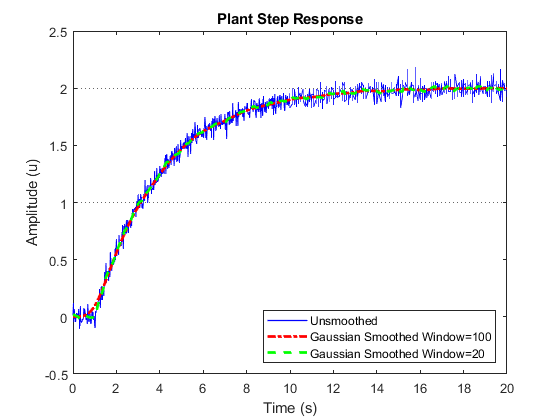

% This matlab script takes open-loop plant step response data, smooths
% it, derives a transfer function, designs 3 different PI controllers
% for the system, and tests the closed-looop step response of the new
% controlled systems.
% 
% The controller tuning methods investigated are the Haglund Astrom,
% Cohen & Coon, and Ziegler Nichols.
% 
% The systems are tested using a unit step at time 0s,
% and a unit step with a following unit disturbance at time 40s.
% 
% Written by Luke Byrne at Glasgow Caledonian University 23/12/2020
 
 
% Wipe workspace
clear
 
% Import the given open loop plant step response data,
% and acompanying timestamps.
% Data files must be in the current working directory.
StepResponse = importdata('response.dat');
RealTime = importdata('time.dat');
 
% Smooth data, to make it easier to derive the transfer function.
% Gaussian Smoothing with two windows were used. A wide window to find
% the maximum amplitude K, and a short window to find the break point Tao.
% Changing these window sizes will change the values for K, Tao and Theta
% used throughout the rest of the analysis
WideWindowSize=100;
ShortWindowsSize=20;
StepResponseHeavilySmoothed = smoothdata(StepResponse,'gaussian', WideWindowSize);
StepResponseLightlySmoothed = smoothdata(StepResponse,'gaussian', ShortWindowsSize);
 
% Imported timestamps have irregular intervals.
% Create new array with same length, but in regular intervals.
IdealTime=[0:0.1:20];
 
% Plot graph of plant step response data.
p=plot(RealTime, StepResponse, 'b', RealTime, StepResponseHeavilySmoothed, 'r-.', RealTime, StepResponseLightlySmoothed, 'g--');
 yline(2, ':')
 yline(1, ':')
 p(1).LineWidth = 1;
 p(2).LineWidth = 2;
 p(3).LineWidth = 2;
 legend('Unsmoothed', strcat('Gaussian Smoothed Window=', num2str(WideWindowSize)), strcat('Gaussian Smoothed Window=', num2str(ShortWindowsSize)), 'Location', 'southeast')
 title('Plant Step Response');
 xlabel('Time (s)');
 ylabel('Amplitude (u)');


 
% Find K, Theta, and Tao from smoothed data.

% K = The final value of the heavily smoothed data.
K= StepResponseHeavilySmoothed(size(StepResponseHeavilySmoothed, 1))

K = 1.9976


% Theta is the point in time when the second derivative of the plant step
% response is largest
% For this the lightly smoothed data is used
StepResponseSecondDerivative=gradient(gradient(StepResponseLightlySmoothed));
[StepResponseSecondDerivativeMax, StepResponseSecondDerivativeIndexAtMax] = max(double(StepResponseSecondDerivative));
Theta=RealTime(StepResponseSecondDerivativeIndexAtMax)

Theta = 1.0200


% Tao equals the point in time at whch the plant step response
% is equal to 0.63 times K, minus Theta
[val,idx]=min(abs(StepResponseHeavilySmoothed-K*0.63));
Tao=RealTime(idx)-Theta

Tao = 3.0200


 
% Dreive open loop plant transfer function, and step response.
PlantTF=tf(K, [Tao 1],'InputDelay', 1)

PlantTF =
 
                1.998
  exp(-1*s) * ----------
              3.02 s + 1
 
Continuous-time transfer function.



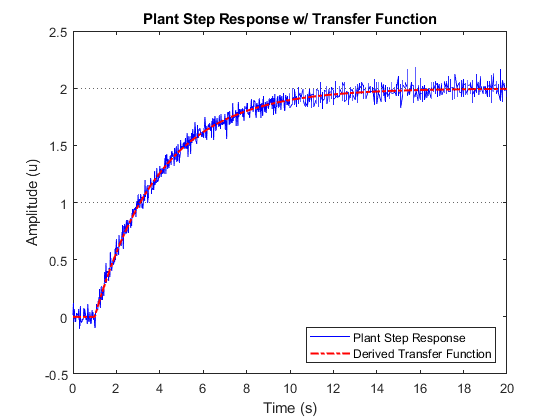

PlantTFStepResponse=step(PlantTF, IdealTime);
 
% Plot plant transfer function on top of noisy data.
plot(RealTime, StepResponse,'b')
 hold on
  plot(IdealTime, PlantTFStepResponse,'r-.', 'LineWidth', 1.5)
  yline(2, ':')
  yline(1, ':')
  legend('Plant Step Response','Derived Transfer Function', 'Location', 'southeast')
  title('Plant Step Response w/ Transfer Function');
  xlabel('Time (s)');
  ylabel('Amplitude (u)');
 hold off

 
% Find values of K_c, and Tao_i,
% and calculate Haglund Astrom controller transfer function.
K_c = (0.14/K)+(0.28*Tao)/(Theta*K)

K_c = 0.4851

Tao_i= (0.33*Theta)+(6.8*Theta*Tao)/(10*Theta+Tao)

Tao_i = 1.9211

K_i = K_c/Tao_i

K_i = 0.2525

HaglundAstromControllerTF=K_c+(tf(K_c, [Tao_i 0]))

HaglundAstromControllerTF =
 
  0.9319 s + 0.4851
  -----------------
       1.921 s
 
Continuous-time transfer function.



 
% Find values of K_c, Tao_i,
% and calculate Cohen & Coon controller transfer function
K_c=(1/K)*(Tao/Theta)*(0.9+Theta/(12*Tao))

K_c = 1.3757

Tao_i=Theta*(30+3*(Theta/Tao))/(9+20*(Theta/Tao))

Tao_i = 2.0078

K_i = K_c/Tao_i

K_i = 0.6851

CohenAndCoonControllerTF=K_c+(tf(K_c, [Tao_i 0]))

CohenAndCoonControllerTF =
 
  2.762 s + 1.376
  ---------------
      2.008 s
 
Continuous-time transfer function.



 
 
% Find the maximum gradient of the open loop plant transfer function step response
PlantTFGradient=gradient(PlantTFStepResponse)*10;
[PlantTFMaxGradient, PlantTFIndexAtMax] = max(double(PlantTFGradient));
PlantTFMaxGradient

PlantTFMaxGradient = 0.6400

PlantTFMaxGradientTime=IdealTime(PlantTFIndexAtMax)

PlantTFMaxGradientTime = 1.1000

PlantTFMaxGradientAmplitude=PlantTFStepResponse(PlantTFIndexAtMax)

PlantTFMaxGradientAmplitude = 0.0651

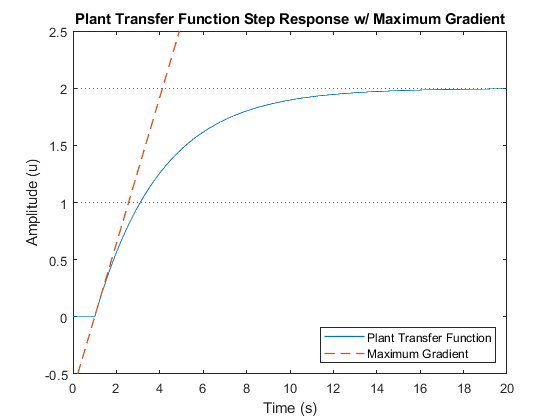

 
% Plot open loop plant transfer function with line of maximum gradient.
plot(IdealTime,PlantTFStepResponse, 'LineWidth', 1)
 hold on
  plot (IdealTime, PlantTFMaxGradientAmplitude+PlantTFMaxGradient*(IdealTime-PlantTFMaxGradientTime),'--',  'LineWidth', 1)
  yline(2, ':')
  yline(1, ':')
  ylim([-0.5 2.5])
  legend('Plant Transfer Function', 'Maximum Gradient', 'Location', 'southeast')
  title('Plant Transfer Function Step Response w/ Maximum Gradient');
  xlabel('Time (s)');
  ylabel('Amplitude (u)');
 hold off

 
% Using maxium gradient, find L, R_n, K_c, and Tao_i
% and calculate Ziegler Nichols Controller transer function.
L=Theta

L = 1.0200

R_n=PlantTFMaxGradient

R_n = 0.6400

K_c=0.9/(R_n*L)

K_c = 1.3786

Tao_i=3*L

Tao_i = 3.0600

K_i = K_c/Tao_i

K_i = 0.4505

ZieglerNicholsControllerTF=K_c+(tf(K_c, [Tao_i 0]))

ZieglerNicholsControllerTF =
 
  4.219 s + 1.379
  ---------------
      3.06 s
 
Continuous-time transfer function.



 
% Calculate closed loop system transfer functions for all 3 controllers.
ClosedLoopHaglundAstrom = feedback(HaglundAstromControllerTF*PlantTF,1);
ClosedLoopCohenAndCoon = feedback(CohenAndCoonControllerTF*PlantTF,1);
ClosedLoopZieglerNichols = feedback(ZieglerNicholsControllerTF*PlantTF,1);

% Calculate gain and phase margins for each controlled system
[HAGm,HAPm,HAWcg,HAWcp] = margin(HaglundAstromControllerTF*PlantTF)

HAGm = 4.3649

HAPm = 53.9709

HAWcg = 1.4507

HAWcp = 0.4046

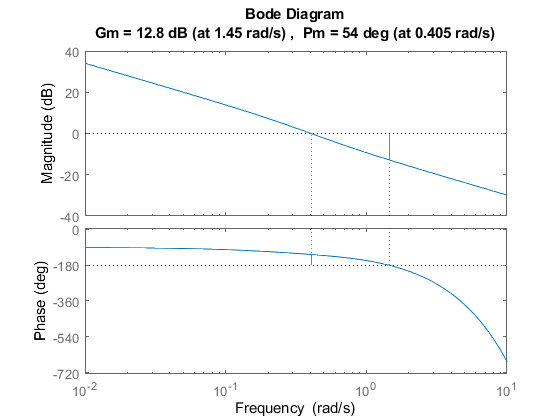

margin(HaglundAstromControllerTF*PlantTF)

[CCGm,CCPm,CCWcg,CCWcp] = margin(CohenAndCoonControllerTF*PlantTF)

CCGm = 1.5632

CCPm = 26.1840

CCWcg = 1.4654

CCWcp = 0.9682

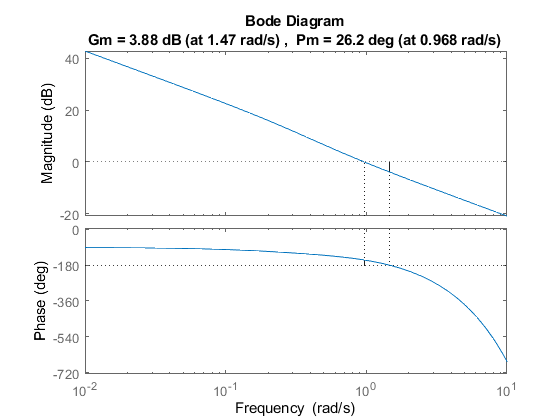

margin(CohenAndCoonControllerTF*PlantTF)

[ZNGm,ZNPm,ZNWcg,ZNWcp] = margin(ZieglerNicholsControllerTF*PlantTF)

ZNGm = 1.7264

ZNPm = 38.0727

ZNWcg = 1.5734

ZNWcp = 0.9105

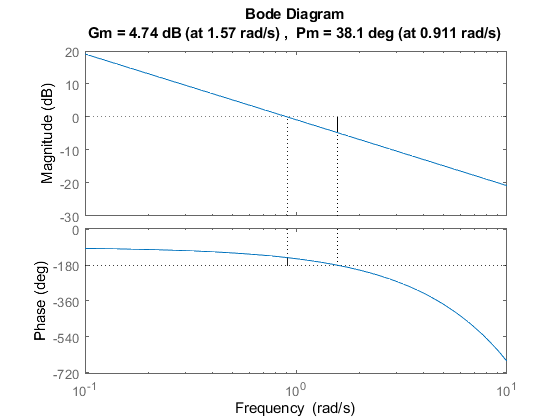

margin(ZieglerNicholsControllerTF*PlantTF)


% Calculate step info for all controllers
ClosedLoopHaglundAstromInfo=stepinfo(ClosedLoopHaglundAstrom)

ClosedLoopHaglundAstromInfo = struct with fields:
        RiseTime: 2.5998
    SettlingTime: 11.3742
     SettlingMin: 0.9140
     SettlingMax: 1.1266
       Overshoot: 12.6587
      Undershoot: 0
            Peak: 1.1266
        PeakTime: 6.7844


ClosedLoopCohenAndCoonInfo=stepinfo(ClosedLoopCohenAndCoon)

ClosedLoopCohenAndCoonInfo = struct with fields:
        RiseTime: 0.8156
    SettlingTime: 14.4034
     SettlingMin: 0.7343
     SettlingMax: 1.6247
       Overshoot: 62.4695
      Undershoot: 0
            Peak: 1.6247
        PeakTime: 3.1455


ClosedLoopZieglerNicholsInfo=stepinfo(ClosedLoopZieglerNichols)

ClosedLoopZieglerNicholsInfo = struct with fields:
        RiseTime: 0.8793
    SettlingTime: 10.9390
     SettlingMin: 0.8392
     SettlingMax: 1.4067
       Overshoot: 40.6674
      Undershoot: 0
            Peak: 1.4067
        PeakTime: 3.0811


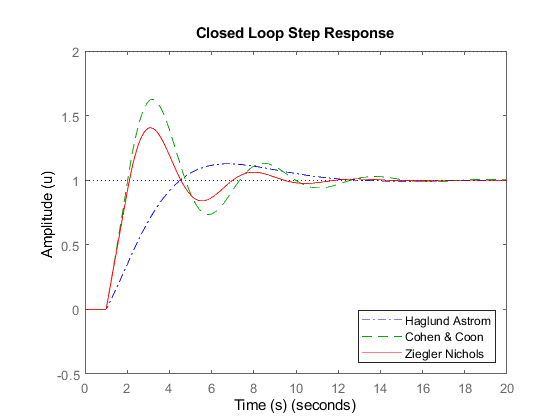


% Plot 3 controllers closed loop unit step response.
stepplot(IdealTime, ClosedLoopHaglundAstrom, 'b-.')
 hold on
  stepplot(IdealTime, ClosedLoopCohenAndCoon, 'g--')
  stepplot(IdealTime, ClosedLoopZieglerNichols, 'r')
  yline(2, ':')
  yline(1, ':')
  ylim([-0.5 2])
  legend('Haglund Astrom', 'Cohen & Coon', 'Ziegler Nichols', 'Location', 'southeast')
  title('Closed Loop Step Response');
  xlabel('Time (s)');
  ylabel('Amplitude (u)');
 hold off

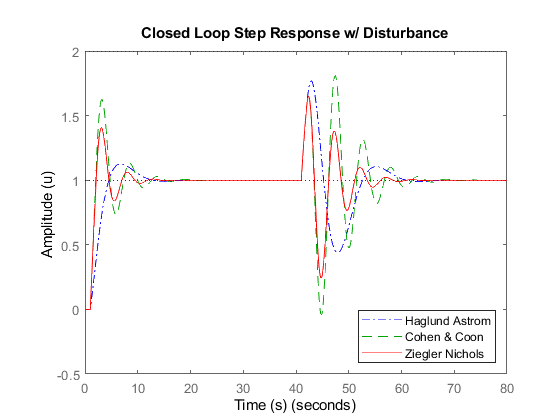


% Create a unit step disturbance of magnatude M at time t.
% Change value of M to see system response to different
% amounts of disturbance
M=1;
t=40;
DisturbanceTF=tf(M,'InputDelay', t);
 
% Calculate closed loop system transfer fucntions for all 3 controllers,
% with a unit step disturbance introduced
ClosedLoopHaglundAstromDisturbance = feedback((HaglundAstromControllerTF+DisturbanceTF)*PlantTF,1);
ClosedLoopCohenAndCoonDisturbance = feedback((CohenAndCoonControllerTF+DisturbanceTF)*PlantTF,1);
ClosedLoopZieglerNicholsDisturbance = feedback((ZieglerNicholsControllerTF+DisturbanceTF)*PlantTF,1);
 
% Plot closed loop system responses, with disturbance
stepplot([0:0.1:80], ClosedLoopHaglundAstromDisturbance, 'b-.')
 hold on
  stepplot([0:0.1:80], ClosedLoopCohenAndCoonDisturbance, 'g--')
  stepplot([0:0.1:80], ClosedLoopZieglerNicholsDisturbance, 'r')
  yline(2, ':')
  yline(1, ':')
  ylim([-0.5 2])
  legend('Haglund Astrom', 'Cohen & Coon', 'Ziegler Nichols',  'Location', 'southeast')
  title('Closed Loop Step Response w/ Disturbance');
  xlabel('Time (s)');
  ylabel('Amplitude (u)');
 hold off


% Cut off the first 40s of the closed loop responses with disturbances,
% and pass the result to a stepinfo() function to get the rise time etc
% for the disturbances only.
% A resolution of 0.0001s in needed to prevent rounding errors
a=step(ClosedLoopHaglundAstromDisturbance, [0:0.0001:80]);
b=a([t*10000:800000]);
HaglundAstromDisturbanceInfo=stepinfo(b, [0:0.0001:40], 1)

HaglundAstromDisturbanceInfo = struct with fields:
        RiseTime: 3.3480e-06
    SettlingTime: 19.7777
     SettlingMin: 0.4383
     SettlingMax: 1.1047
       Overshoot: 76.8347
      Undershoot: 0
            Peak: 1.7683
        PeakTime: 2.8908



a=step(ClosedLoopCohenAndCoonDisturbance, [0:0.0001:80]);
b=a([t*10000:800000]);
CohenAndCoonDisturbanceInfo=stepinfo(b, [0:0.0001:40], 1)

CohenAndCoonDisturbanceInfo = struct with fields:
        RiseTime: 3.0854
    SettlingTime: 23.8242
     SettlingMin: -0.0415
     SettlingMax: 1.8103
       Overshoot: 81.0295
      Undershoot: 4.1504
            Peak: 1.8103
        PeakTime: 7.4216



a=step(ClosedLoopZieglerNicholsDisturbance, [0:0.0001:80]);
b=a([t*10000:800000]);
ZieglerNicholsDisturbanceInfo=stepinfo(b, [0:0.0001:40], 1)

ZieglerNicholsDisturbanceInfo = struct with fields:
        RiseTime: 0.7738
    SettlingTime: 17.6672
     SettlingMin: 0.2423
     SettlingMax: 1.6493
       Overshoot: 64.9262
      Undershoot: 0
            Peak: 1.6493
        PeakTime: 2.3705


% Open and Run Simulink systems
% System files must be inside the current working directory directory
Saturation=sim("Saturation.slx");

AntiWindup=sim("AntiWindup.slx");

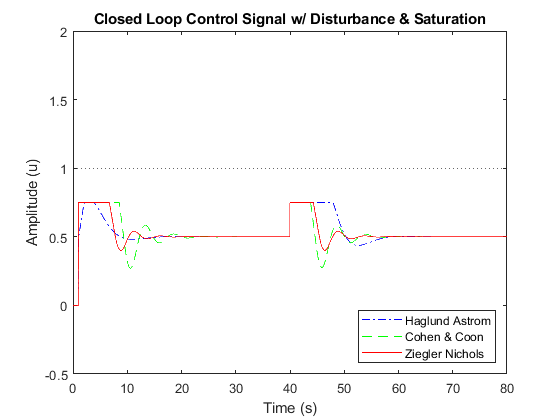

% Plot Simulink saturation block outputs
plot(Saturation.HaglundAstrom, 'b-.')
 hold on
  plot(Saturation.CohenAndCoon, 'g--')
  plot(Saturation.ZieglerNichols, 'r')
  yline(2, ':')
  yline(1, ':')
  ylim([-0.5 2])
  legend('Haglund Astrom', 'Cohen & Coon', 'Ziegler Nichols',  'Location', 'southeast')
  title('Closed Loop Control Signal w/ Disturbance & Saturation');
  xlabel('Time (s)');
  ylabel('Amplitude (u)');
 hold off

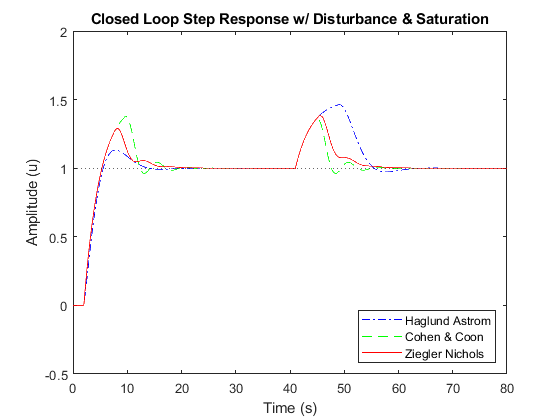

 
% Plot SIMULINK Saturated system outputs
plot(Saturation.SystemHaglundAstrom, 'b-.')
 hold on
  plot(Saturation.SystemCohenAndCoon, 'g--')
  plot(Saturation.SystemZieglerNichols, 'r')
  yline(2, ':')
  yline(1, ':')
  ylim([-0.5 2])
  legend('Haglund Astrom', 'Cohen & Coon', 'Ziegler Nichols',  'Location', 'southeast')
  title('Closed Loop Step Response w/ Disturbance & Saturation');
  xlabel('Time (s)');
  ylabel('Amplitude (u)');
 hold off


 
% Extract data from simulink saturation system outputs,
% for use when extracting step info
SaturationHaglundAstrom=Saturation.HaglundAstrom.Data;
SaturationCohenAndCoon=Saturation.CohenAndCoon.Data;
SaturationZieglerNichols=Saturation.ZieglerNichols.Data;

SystemHaglundAstrom=Saturation.SystemHaglundAstrom.Data;
SystemCohenAndCoon=Saturation.SystemCohenAndCoon.Data;
SystemZieglerNichols=Saturation.SystemZieglerNichols.Data;
 
% Split Simulink saturation output data into only the step,
% and only the disturbance for use in stepinfo() function
HaglundAstromWithSaturationStep=SystemHaglundAstrom([1:400001]);
HaglundAstromWithSaturationDisturbance=SystemHaglundAstrom([400001:800001]);

CohenAndCoonWithSaturationStep=SystemCohenAndCoon([1:400001]);
CohenAndCoonWithSaturationDisturbance=SystemCohenAndCoon([400001:800001]);

ZieglerNicholsWithSaturationStep=SystemZieglerNichols([1:400001]);
ZieglerNicholsWithSaturationDisturbance=SystemZieglerNichols([400001:800001]);


% Get step info for saturation outputs
HaglundAstromWithSaturationStepInfo=stepinfo(HaglundAstromWithSaturationStep, [0:0.0001:40], 1) 

HaglundAstromWithSaturationStepInfo = struct with fields:
        RiseTime: 2.6726
    SettlingTime: 12.4904
     SettlingMin: 0.9000
     SettlingMax: 1.1324
       Overshoot: 13.2359
      Undershoot: 0
            Peak: 1.1324
        PeakTime: 7.8426


CohenWithSaturationStepInfo=stepinfo(CohenAndCoonWithSaturationStep, [0:0.0001:40], 1) 

CohenWithSaturationStepInfo = struct with fields:
        RiseTime: 2.5632
    SettlingTime: 16.5734
     SettlingMin: 0.9000
     SettlingMax: 1.3787
       Overshoot: 37.8740
      Undershoot: 0
            Peak: 1.3787
        PeakTime: 9.7289


ZieglerNicholsWithSaturationStepInfo=stepinfo(ZieglerNicholsWithSaturationStep, [0:0.0001:40], 1) 

ZieglerNicholsWithSaturationStepInfo = struct with fields:
        RiseTime: 2.5632
    SettlingTime: 15.2393
     SettlingMin: 0.9000
     SettlingMax: 1.2892
       Overshoot: 28.9246
      Undershoot: 0
            Peak: 1.2892
        PeakTime: 8.1738



HaglundAstromWithSaturationDisturbanceInfo=stepinfo(HaglundAstromWithSaturationDisturbance, [0:0.0001:40], 1) 

HaglundAstromWithSaturationDisturbanceInfo = struct with fields:
        RiseTime: 3.3334e-05
    SettlingTime: 21.3232
     SettlingMin: 0.9725
     SettlingMax: 1.0017
       Overshoot: 46.3516
      Undershoot: 0
            Peak: 1.4635
        PeakTime: 9.0950


CohenAndCoonWithSaturationDisturbanceInfo=stepinfo(CohenAndCoonWithSaturationDisturbance, [0:0.0001:40], 1) 

CohenAndCoonWithSaturationDisturbanceInfo = struct with fields:
        RiseTime: 0.5511
    SettlingTime: 16.4529
     SettlingMin: 0.9618
     SettlingMax: 1.3626
       Overshoot: 36.2618
      Undershoot: 0
            Peak: 1.3626
        PeakTime: 5.0385


ZieglerNicholsWithSaturationDisturbanceInfo=stepinfo(ZieglerNicholsWithSaturationDisturbance, [0:0.0001:40], 1)

ZieglerNicholsWithSaturationDisturbanceInfo = struct with fields:
        RiseTime: NaN
    SettlingTime: 17.2944
     SettlingMin: NaN
     SettlingMax: NaN
       Overshoot: 38.3995
      Undershoot: 0
            Peak: 1.3840
        PeakTime: 5.5685


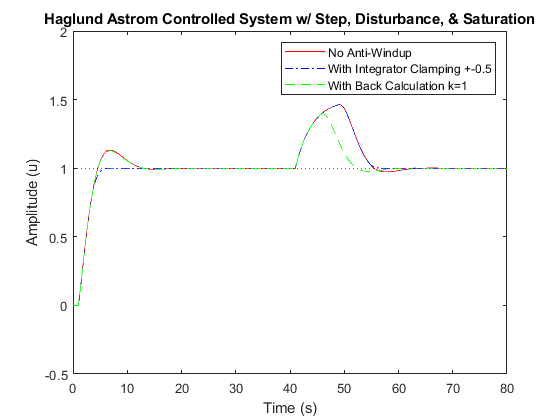


% Plot SIMULINK anti-Windup results
plot(AntiWindup.NoAntiWindup, 'r')
 hold on
  plot(AntiWindup.IntegratorClamped, 'b-.')
  plot(AntiWindup.BackCalculation, 'g--')
  yline(2, ':')
  yline(1, ':')
  ylim([-0.5 2])
  legend('No Anti-Windup', 'With Integrator Clamping +-0.5', 'With Back Calculation k=1')
  title('Haglund Astrom Controlled System w/ Step, Disturbance, & Saturation');
  xlabel('Time (s)');
  ylabel('Amplitude (u)');
 hold off

 
% Extract data from simulink anti-windup system outputs,
% for use when extracting step info
NoAntiWindup=AntiWindup.NoAntiWindup.Data;
IntegratorClamped=AntiWindup.IntegratorClamped.Data;
BackCalculation=AntiWindup.BackCalculation.Data;

SaturationHaglundAstrom=Saturation.HaglundAstrom.Data;
SaturationCohenAndCoon=Saturation.CohenAndCoon.Data;
SaturationZieglerNichols=Saturation.ZieglerNichols.Data;

SystemHaglundAstrom=Saturation.SystemHaglundAstrom.Data;
SystemCohenAndCoon=Saturation.SystemCohenAndCoon.Data;
SystemZieglerNichols=Saturation.SystemZieglerNichols.Data;
 

% Split Simulink saturation output data into only the step,
% and only the disturbance for use in stepinfo() function
NoAntiWindupStep=AntiWindup.NoAntiWindup.Data([1:400001]);
NoAntiWindupDisturbance=AntiWindup.NoAntiWindup.Data([400001:800001]);

IntegratorClampedStep=AntiWindup.IntegratorClamped.Data([1:400001]);
IntegratorClampedDisturbance=AntiWindup.IntegratorClamped.Data([400001:800001]);

BackCalculationStep=AntiWindup.BackCalculation.Data([1:400001]);
BackCalculationDisturbance=AntiWindup.BackCalculation.Data([400001:800001]);


% Get step info for anti-windup outputs
NoAntiWindupStepInfo=stepinfo(NoAntiWindupStep, [0:0.0001:40], 1) 

NoAntiWindupStepInfo = struct with fields:
        RiseTime: 2.6726
    SettlingTime: 11.4907
     SettlingMin: 0.9000
     SettlingMax: 1.1323
       Overshoot: 13.2312
      Undershoot: 0
            Peak: 1.1323
        PeakTime: 6.8428


IntegratorClampedStepInfo=stepinfo(IntegratorClampedStep, [0:0.0001:40], 1) 

IntegratorClampedStepInfo = struct with fields:
        RiseTime: 2.7917
    SettlingTime: 5.1472
     SettlingMin: 0.9000
     SettlingMax: 1.0007
       Overshoot: 0.0689
      Undershoot: 0
            Peak: 1.0007
        PeakTime: 7.1359


BackCalculationStepInfo=stepinfo(BackCalculationStep, [0:0.0001:40], 1) 

BackCalculationStepInfo = struct with fields:
        RiseTime: 2.6770
    SettlingTime: 11.4614
     SettlingMin: 0.9000
     SettlingMax: 1.1266
       Overshoot: 12.6566
      Undershoot: 0
            Peak: 1.1266
        PeakTime: 6.8621



NoAntiWindupDisturbanceInfo=stepinfo(NoAntiWindupDisturbance, [0:0.0001:40], 1) 

NoAntiWindupDisturbanceInfo = struct with fields:
        RiseTime: 4.9349e-05
    SettlingTime: 21.3242
     SettlingMin: 0.9725
     SettlingMax: 1.0017
       Overshoot: 46.3521
      Undershoot: 0
            Peak: 1.4635
        PeakTime: 9.0955


IntegratorClampedDisturbanceInfo=stepinfo(IntegratorClampedDisturbance, [0:0.0001:40], 1) 

IntegratorClampedDisturbanceInfo = struct with fields:
        RiseTime: 0.0025
    SettlingTime: 15.5670
     SettlingMin: 0.9992
     SettlingMax: 1.4635
       Overshoot: 46.3474
      Undershoot: 0
            Peak: 1.4635
        PeakTime: 9.0946


BackCalculationDisturbanceInfo=stepinfo(BackCalculationDisturbance, [0:0.0001:40], 1)

BackCalculationDisturbanceInfo = struct with fields:
        RiseTime: 5.4482e-05
    SettlingTime: 18.1555
     SettlingMin: 0.9763
     SettlingMax: 1.0015
       Overshoot: 39.6327
      Undershoot: 0
            Peak: 1.3963
        PeakTime: 6.0097
